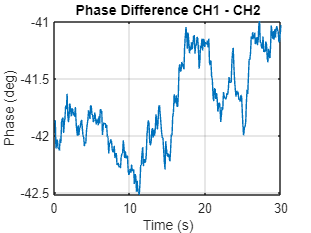

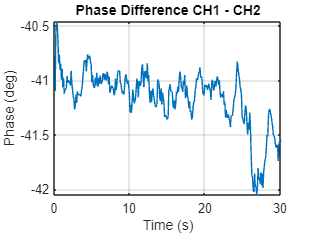

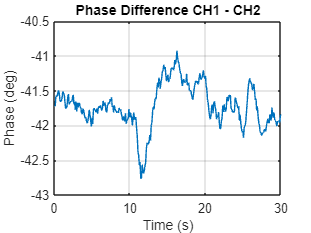

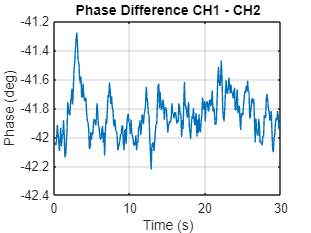

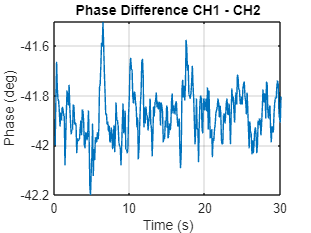

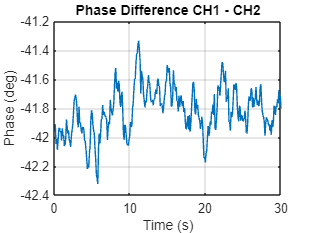

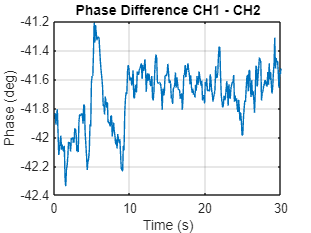

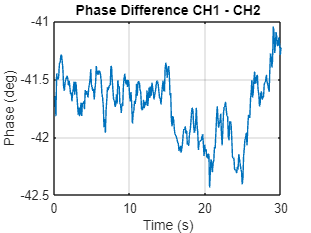

% Clear MATLAB workspace of any previous instrument connections
clear; clc;

num_trials = 10;
% UPDATE PER TEST:
motion = 1; % 1: no motion, 2: slow, 3: fast
obstacle = 2; % 1: no bricks, 2: bricks
distance = 7; % 1: 0.2m, 2: 0.4m, 3: 0.6m, 4: 0.8m, 5: 1.0, 6: 1.2m, 7: 1.4m

% Provide the Resource name of the oscilloscope - Note you will have to
% change this to match your oscilloscope.
visaAddress = "USB0::0x0699::0x0421::C026909::0::INSTR";
% Create a VISA object and set the |InputBufferSize| to allow for transfer
% of waveform from oscilloscope to MATLAB. Tek VISA needs to be installed.
scope = visadev(visaAddress);

scope.flush("input");
scope.flush("output");
scope.InputBufferSize = 2048;
% Set the |ByteOrder| to match the requirement of the instrument
scope.ByteOrder = 'little-endian';
% Open the connection to the oscilloscope

%scope.writeread("DISplay:PERSistence?")

% Reset the oscilloscope to a known state
scope.write('CH1:TERmination FIFty');
scope.write('CH2:TERmination FIFty');
%:SELECT:MATH ON
%scope.write('AUTOSET EXECUTE;:SELECT:CH1 ON;:SELECT:CH2 ON;:SELECT:MATH ON');

for trial = 1:num_trials
% generate saved filename
filename = sprintf("test_%i_%i_%i_%i.csv",distance,motion,obstacle,trial);

% Turn headers off, this makes parsing easier
scope.write(':HEADer 0');
%scope.write("MATH:TYPE ADVANCED;");
str = "MATH:TYPE ADVANCED;:DEFINE";
q = char(34);
str = strcat(str,q," PHA(CH1,CH2)",q);
%str = strcat(str, " PHAse(CH1, CH2)");
%scope.write(str);
scope.write(":DATa:SOUrce MATH");
scope.write(":DATa:STARt 100")
scope.write(":DATa:STOP 100")

%scope.writeread("MEASUrement:IMMed:TYPe?")
scope.writeread("MATH?");

% Request 16 bit binary data on the CURVE query
%scope.write(":DATa:ENCdg BN_FMt");
%scope.write(":WFMInpre:YOFf 0.0E+0")
yscale = str2double(scope.writeread(":WFMInpre:YMUlt?"));
%fprintf(myScope, 'DATA:ENCDG RIBINARY;WIDTH 1');
%scope.write('DATA:ENCDG RIBINARY;WIDTH 2');


% Initialize variables
data = [];
t = [];
index = 1;
%scope.writeread(":WFMOutpre?")
scope.write("ACQuire:STATE ON");
scope.write("ACQuire:STOPAfter RUNSTop");
scope.write('ACQuire:MODe AVErage');
scope.write('ACQuire:NUMAVg 256');
%phase = scope.writeread("MEASUrement:IMMed:Units?")
tic; % Start timer
% Continuous data acquisition loop
while toc < 30
    %scope.write("ACQuire:STATE RUN")
    phase = scope.writeread("CURVE?");
    t = [t,toc]; % Record time
    data = [data, str2double(phase)];
end
data = data .* yscale;
%data = (str2double(verticalScale) * (binblockread(myScope,'int8')))' + str2double(yOffset);
% Clean up Close the connection
% Clear the variable
%clear scope;
% Plot the acquired data and add axis labels
%scatter(1:length(data), data);
figure;
plot(t, data)
xlabel('Time (s)'); 
ylabel('Phase (deg)');
title('Phase Difference CH1 - CH2');
grid on;

% save to a .mat and .csv file
%save(strcat(filename,".mat"), 't','data');
%save(strcat(filename,".csv"), 't','data','');
t = t';
data = data';
writematrix([t, data],filename);
end

clear scope;